# Sprawozdanie z Laboratorium 7

Karolina Piotrowska

### Zadanie 1

clear all; close all
syms t w
N = 10; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
Xk = zeros(1,N);
for k = 0:N-1 % impl. wzoru (8)
for n = 0:N-1
    Xk(k+1) = Xk(k+1) + xn(n+1)*exp(-1j*2*pi/N*k*n);
end
end
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 1.2616e-13

disp('DFT error:'); disp(dft_err);

DFT error:
   1.2616e-13



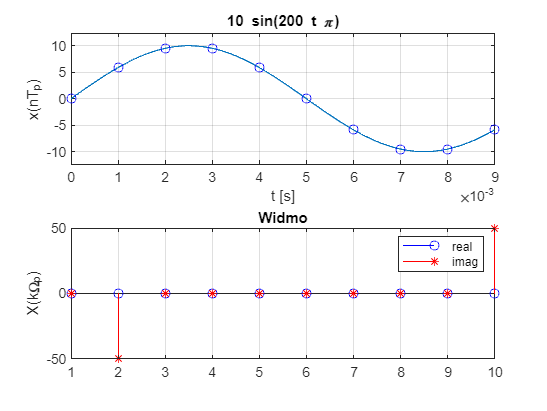

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
stem(real(Xk),'ob'); grid on, hold on
stem(imag(Xk),'*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag')

### Zadanie 2

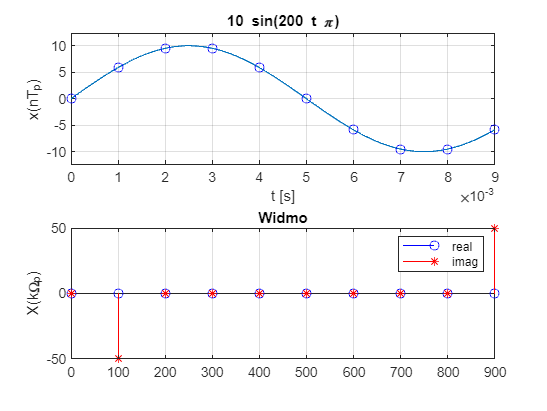

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
wk = fp*[0:N-1]/N;    % oś częstotliwości
% należy przekazać funkcji stem() wartości na osi X
stem(wk, real(Xk), 'ob'); grid on; hold on;
stem(wk, imag(Xk), '*r');
title('Widmo'),
ylabel('X(k\Omega_p)'); %xlabel('f [Hz]')
legend('real','imag');

### Zadanie 3

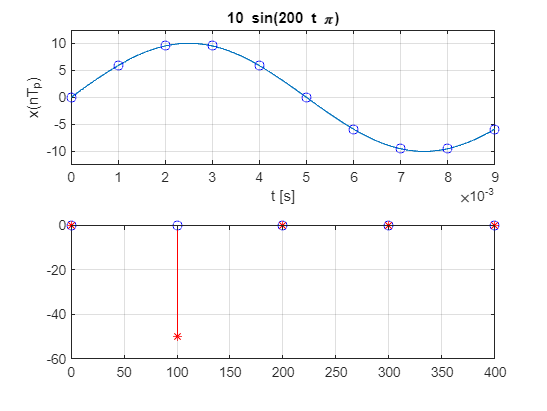

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
wk = fp*[0:((N/2)-1)]/N;    % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');

### Zadanie 4

figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
wk = fp*[0:((N/2)-1)]/N;    % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');

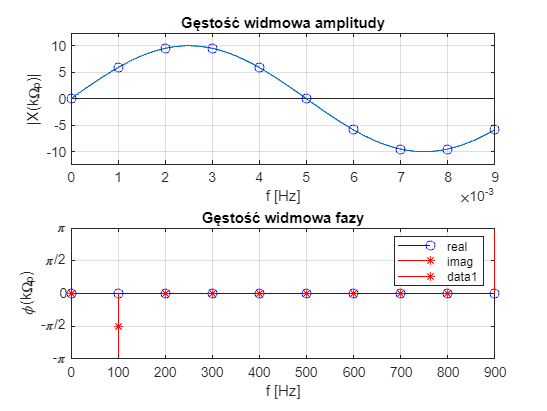

tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');

### Zadanie 5

5.1

dft_err = 9.5509e-13

DFT error:
   9.5509e-13



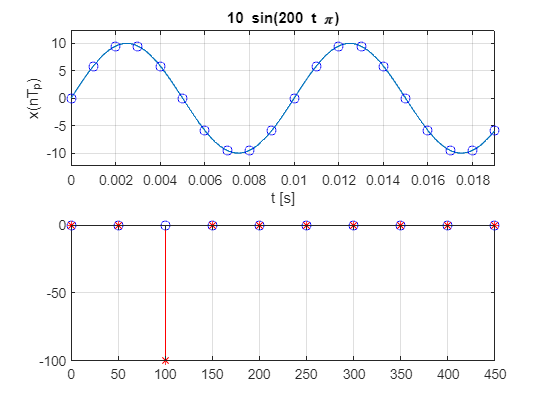

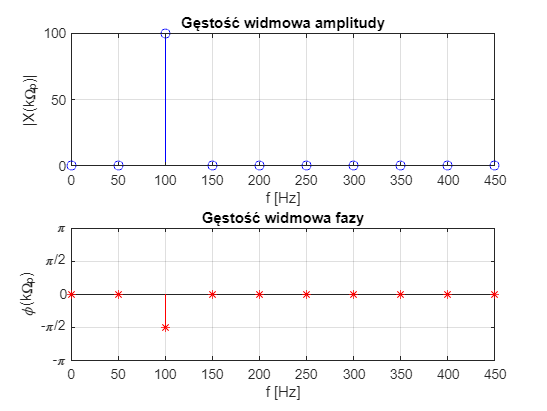

clear all; close all
zad56(20,100)

Przy dwukrotnym zwiększeniu liczby próbek, moc sygnału również wzrosła dwukrotnie, natomiast faza nie zmieniła się.

5.2

dft_err = 6.7921e-13

DFT error:
   6.7921e-13



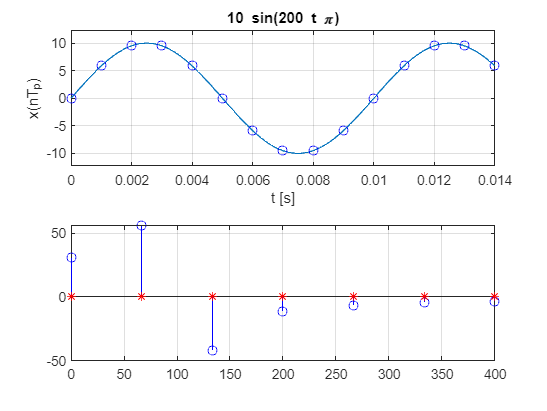

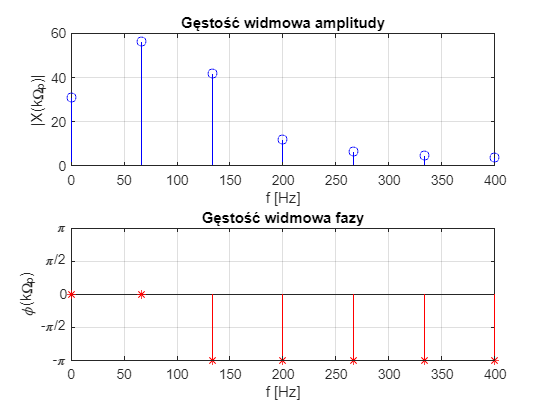

clear all; close all
zad56(15,100)

Z powodu braku próbki odpowiadającej dokładnie częstotliwości sygnału, energia rozłożyła się na inne próbki, szczególnie na te najbliższe brakującej. Pojawiła się stała składowa, któej nie ma w oryginalnym sygnale.

### Zadanie 6

dft_err = 1.4156e-13

DFT error:
   1.4156e-13



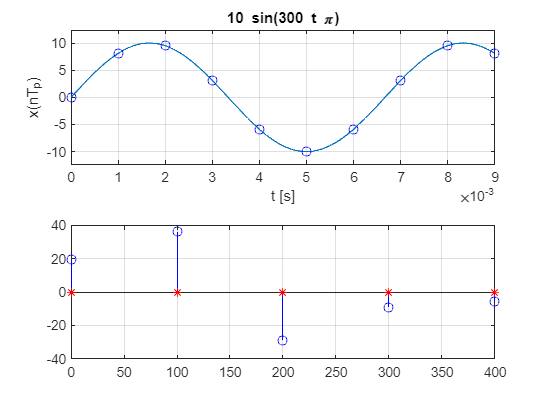

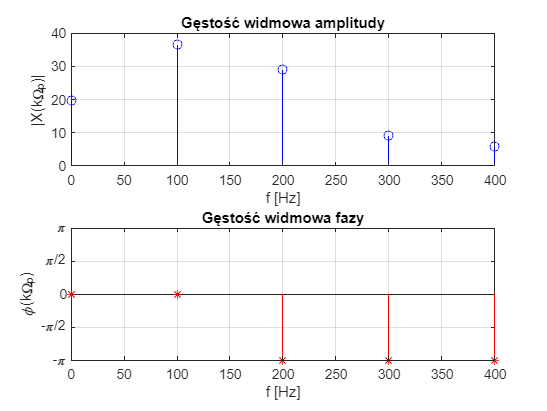

clear all; close all
zad56(10,150)

Ponownie, z powodu braku próbki odpowiadającej częstotliwości sygnału, obserwujemy zjawisko przecieku widma.

### Zadanie 7

7.1 Okna trójkątne

dft_err = 5.0804e-14

DFT error:
   5.0804e-14



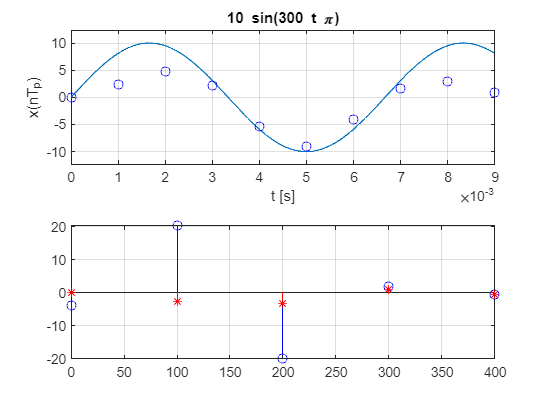

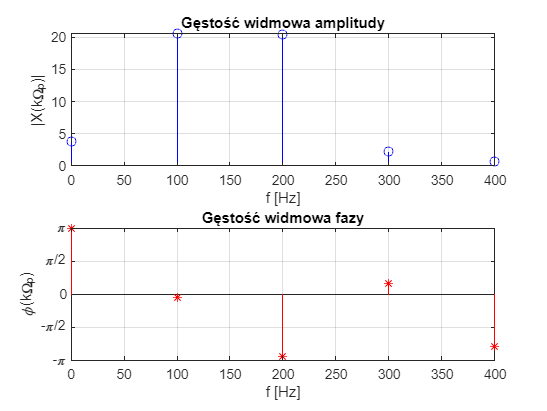

clear all; close all
zad7('tr')

7.2 Okna Gaussa

dft_err = 5.7182e-14

DFT error:
   5.7182e-14



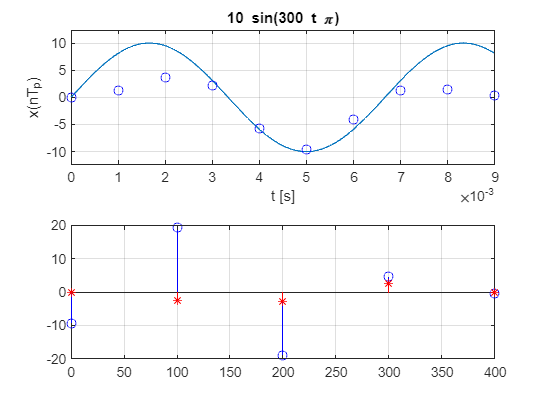

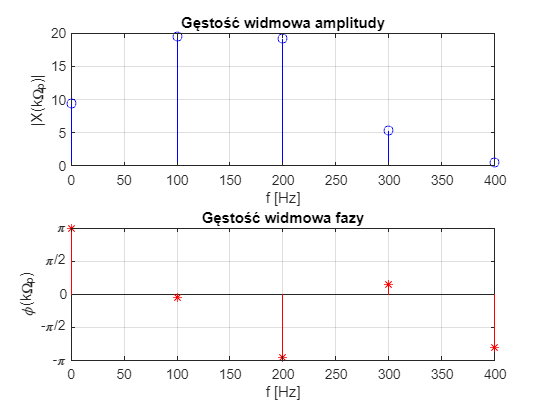

clear all; close all
zad7('ga')

7.3 Okna Czebyszewa

dft_err = 5.7886e-14

DFT error:
   5.7886e-14



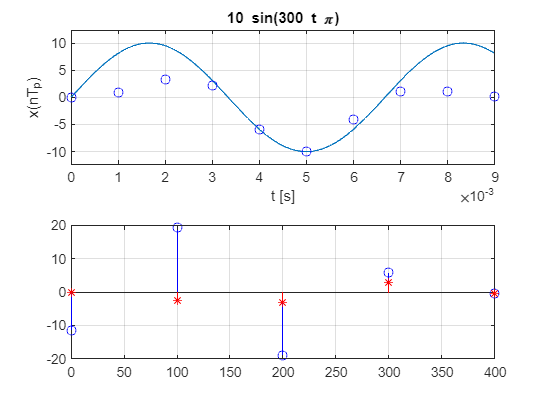

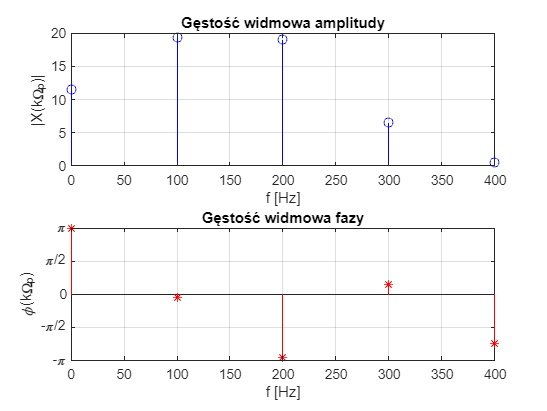

clear all; close all
zad7('ch')

Zastosowanie okna trójkątnego dało najlepszy efekt; w pozostałych przypadkach w ogóle nie została odfiltrowana stała składowa niewystępująca w oryginalnym sygnale. 

### Zadanie 8

8.1

dft_err = 1.2653e-12

DFT error:
   1.2653e-12



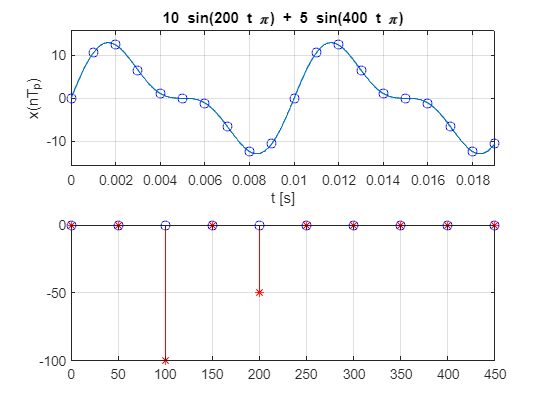

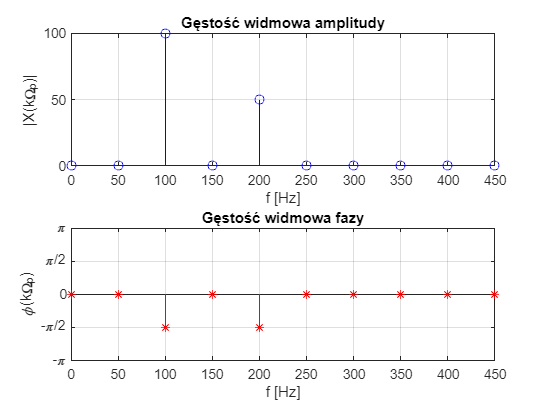

clear all; close all
zad8(0)

8.2

dft_err = 1.4323e-12

DFT error:
   1.4323e-12



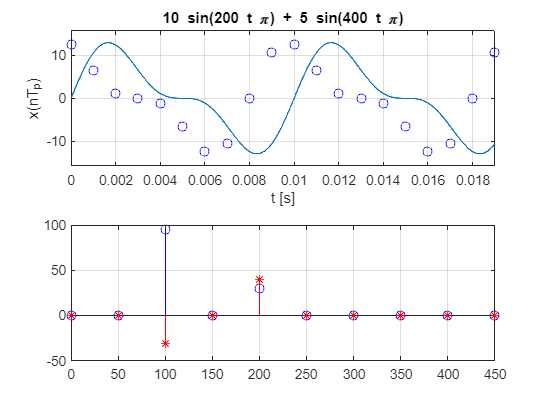

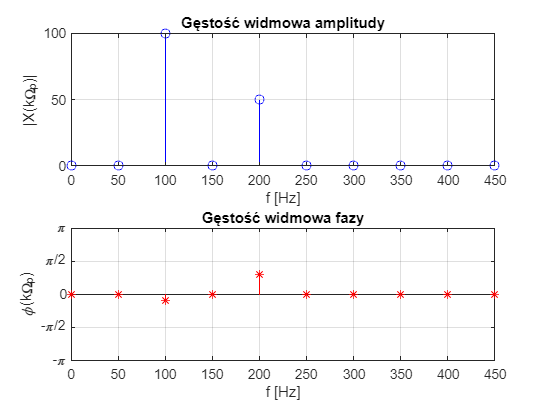

clear all; close all
zad8(2)

Po przesunięciu cyklicznym gęstość widmowa zostaje cała, a zmienia się faza sygnału.

### Zadanie 9 (ZD)

clear all; close all
syms t w
N = 20; % liczba próbek
fp = 1000;%Hz
Tp = 1/fp;
A0 = 5;
A1 = 10; f1 = 100; %Hz
x1 = A1*sin(2*pi*f1*t);
x = x1;
tn = [0:N-1]*Tp; % wsp. czasowe próbek
xn = double(subs(x,t,tn));
W = dftmtx(N);
Xk = xn*W;
Xk_fft = fft(xn,N); %funkcja wbudowana
dft_err = sum(abs(Xk_fft-Xk))

dft_err = 5.2563e-14

disp('DFT error:'); disp(dft_err);

DFT error:
   5.2563e-14



figure;
subplot(2,1,1)
ezplot(x,[tn(1),tn(N)]); hold on; grid on
plot(tn, xn,'ob');
xlabel('t [s]'); ylabel('x(nT_p)');
subplot(2,1,2)
wk = fp*[0:((N/2)-1)]/N;    % oś częstotliwości
stem(wk, real(Xk(1:N/2)), 'ob'); grid on; hold on;
stem(wk, imag(Xk(1:N/2)), '*r');

tol = 1e-2;
Xk(abs(Xk) < tol) = 0;
figure(2);
subplot(2,1,1);
stem(wk, abs(Xk(1:N/2)), 'ob'); grid on; hold on;
ylabel('|X(k\Omega_p)|');
title('Gęstość widmowa amplitudy');
xlabel('f [Hz]');
subplot(2,1,2);
stem(wk, angle(Xk(1:N/2)), '*r'); grid on;
yticks([-2*pi, -1.5*pi, -pi, -pi/2, 0, pi/2, pi, 1.5*pi, 2*pi]);
ylim([-pi, pi]);
yticklabels({'-2\pi', '-3/2\pi', '-\pi','-\pi/2','0','\pi/2','\pi', '3/2\pi', '2\pi'})
ylabel('\phi(k\Omega_p)');
title('Gęstość widmowa fazy');
xlabel('f [Hz]');